clc;
clear;
format shortE;

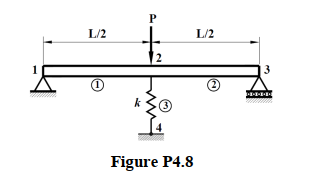

Taking inputs about elements

nel=2%input("Enter the number of beam elements: ");

nel =      2


nk=1%input("Enter the number of spring elements: ");

nk =      1


nnd= nel+nk+1; %Number of nodes
dof=2*nnd-1; % Degree of freedom for a planar beam
E=200e9;
I=0.8e-4;
l=[4 4];
P=10e3;
k=5e6;

Creating empty global stiffness matrix, force and displacement vector

gstiff=zeros(dof,dof);
gforce=zeros(dof,1);
gdisp=zeros(dof,1);
kel=cell(nel,1);

Calculating global stiffness matrix

for n=1:nel
    i=n;
    j=n+1;
    ix=2*i-1;
    iy=2*i;
    jx=2*j-1;
    jy=2*j;
    %l(n)=input(sprintf("Enter the length of element %d : ",n));
    L=l(n);
    %el(n)=input(sprintf("Enter the modulus of elasticity of element %d : ",n));
    %E=el(n);
    %i(n)=input(sprintf("Enter the moment of inertia for element %d : ",n));
    %I=i(n);
    kel{n}=[12*E*I/L^3 6*E*I/L^2 -12*E*I/L^3 6*E*I/L^2
    6*E*I/L^2 4*E*I/L -6*E*I/L^2 2*E*I/L
    -12*E*I/L^3 -6*E*I/L^2 12*E*I/L^3 -6*E*I/L^2
    6*E*I/L^2 2*E*I/L -6*E*I/L^2 4*E*I/L
    ]
    kel{n}
    gstiff([ix,iy,jx,jy],[ix,iy,jx,jy])=gstiff([ix,iy,jx,jy],[ix,iy,jx,jy])+kel{n};
end

kel = 2×1 cell array
    {4×4 double}
    {0×0 double}


ans =    3.0000e+06   6.0000e+06  -3.0000e+06   6.0000e+06
   6.0000e+06   1.6000e+07  -6.0000e+06   8.0000e+06
  -3.0000e+06  -6.0000e+06   3.0000e+06  -6.0000e+06
   6.0000e+06   8.0000e+06  -6.0000e+06   1.6000e+07


kel = 2×1 cell array
    {4×4 double}
    {4×4 double}


ans =    3.0000e+06   6.0000e+06  -3.0000e+06   6.0000e+06
   6.0000e+06   1.6000e+07  -6.0000e+06   8.0000e+06
  -3.0000e+06  -6.0000e+06   3.0000e+06  -6.0000e+06
   6.0000e+06   8.0000e+06  -6.0000e+06   1.6000e+07


Including spring in global stiffness

for q=1:nk
    k(q)=k%input(sprintf("Enter the stiffness of spring %d: ",q));
    disp("Consider the orientation of spring in finding common node and displacement to beam. ");
    h=[3 7]%input("Enter the displacements affected by the spring as per position in global stiffness matrix: ");
    gstiff(h,h)=gstiff(h,h)+ k(q)*[1 -1;-1 1];
end

k =      5000000


Consider the orientation of spring in finding common node and displacement to beam. 


h =      3     7


gstiff

gstiff =    3.0000e+06   6.0000e+06  -3.0000e+06   6.0000e+06            0            0            0
   6.0000e+06   1.6000e+07  -6.0000e+06   8.0000e+06            0            0            0
  -3.0000e+06  -6.0000e+06   1.1000e+07            0  -3.0000e+06   6.0000e+06  -5.0000e+06
   6.0000e+06   8.0000e+06            0   3.2000e+07  -6.0000e+06   8.0000e+06            0
            0            0  -3.0000e+06  -6.0000e+06   3.0000e+06  -6.0000e+06            0
            0            0   6.0000e+06   8.0000e+06  -6.0000e+06   1.6000e+07            0
            0            0  -5.0000e+06            0            0            0   5.0000e+06


Applying boundary conditions of externally applied loads

load_vector=3%input("Enter the position of external loads applied as they would be positioned in global force vector: ");

load_vector =      3


extloads=-P%input("Enter the external loads applied :");

extloads =       -10000


gforce(load_vector)=extloads

gforce =            0
           0
      -10000
           0
           0
           0
           0


gforce

gforce =            0
           0
      -10000
           0
           0
           0
           0


Calculation of required displacements

g=[2 3 4 6]%input("Enter the displacements to be found according to their position in the stiffness matrix:");

g =      2     3     4     6


Extracting the required stiffness matrix

gstiff1=gstiff(g,g)

gstiff1 =    1.6000e+07  -6.0000e+06   8.0000e+06            0
  -6.0000e+06   1.1000e+07            0   6.0000e+06
   8.0000e+06            0   3.2000e+07   8.0000e+06
            0   6.0000e+06   8.0000e+06   1.6000e+07


gforce1=gforce(g)

gforce1 =            0
      -10000
           0
           0


disp1=gstiff1\gforce1

disp1 =   -5.7692e-04
  -1.5385e-03
   1.6860e-20
   5.7692e-04


gdisp(g)=disp1;

The required nodal displacements and support reactions are:-

gdisp

gdisp =             0
  -5.7692e-04
  -1.5385e-03
   1.6860e-20
            0
   5.7692e-04
            0


force=gstiff*gdisp

force =    1.1538e+03
   1.3488e-13
  -1.0000e+04
            0
   1.1538e+03
  -1.8190e-12
   7.6923e+03
